# SDO Analysis (Quick-Run Demonstration)

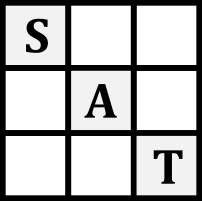

A Visual Demonstration of the SDO Analysis Toolkit (SAT).

In this exercise, we will perform an SDO analysis using the included custom classes for importing, manipulating, and plotting data. This script may serve as a basis for customized analysis, or as as quick-run validation of the installation and demonstration of the undelrying method.

_________________________________________________

Copyright (C) 2023 Trevor S. Smith

Drexel University College of Medicine

*This program is free software: you can redistribute it and/or modify it under the terms of the GNU General Public License as published by the Free Software Foundation, either version 3 of the License, or (at your option) any later version.*

*This program is distributed in the hope that it will be useful, but WITHOUT ANY WARRANTY; without even the implied warranty of MERCHANTABILITY or FITNESS FOR A PARTICULAR PURPOSE.  See the GNU General Public License for more details.*

*You should have received a copy of the GNU General Public License along with this program.  If not, see <https://www.gnu.org/licenses/>.*

__________________________________________

## **INSTRUCTIONS**: 

NOTE: Execution of this script is expected to take ~5 min. 

Load in both *xtData.m* and *ppData.m* in the prompted order. Use the below 'load' buttons to point to the ppData.mat and xtData.mat datasets. 

%This short bit of code uses the a UI to grab the files. 
ppFile= "C:\Users\Frog\OneDrive - Drexel University\TSAnalysis\sdoAnalysis\sat-master\demoData\example_ppData.mat";
xtFile="C:\Users\Frog\OneDrive - Drexel University\TSAnalysis\sdoAnalysis\sat-master\demoData\example_xtData.mat";
% -- Load data into expected format; 
xtData0 = load(xtFile); 
ppData0 = load(ppFile); 
xtfield = fields(xtData0); 
ppfield = fields(ppData0); 
xtData = xtData0.(xtfield{1}); 
ppData = ppData0.(ppfield{1}); 
% at this point, we should have variables 'xtData' and 'ppData' in the
% workspace

If you have the 'Parallel Computing' MATLAB add-on, you can select the below box. This will greatly speed up the calculations for SDO estimation, which is especially useful for use in the *sdoMultiMat* class. 

parallelCompute = true; 

**SDO Matrix Estimation Algorithm:** 

The SDO matrix is not uniquely defined. Various methods may be used to estimate the SDO matrix, conferring alternative properties.

*Exact*: Calculate the SDO which matches $\Delta p\left(x\right)=L\;p\left(x\right)$

        
$$L=p\left(x_1 \right)\bigotimes p\left(x_0 \right)-\mathrm{Diag}\left(p\left(x_0 \right)\right)$$


Asymmetric: Calculate an SDO which only assigns values where $p\left(x_1 =i\right)>p\left(x_0 =i\right)$, prioritizing changes in the mean, better ellucidating matrix motifs. 

        
$$L_+ =\;\max \left(p\left(x_1 \right)-p\left(x_0 \right),0\right)\bigotimes p\left(x_0 \right)$$


estimationMethod = "original"; 

estimationMethod = "original"

Create and populate instances of the *xtDataCell* and *ppDataCell* classes to operate on the time series and point-process data, respectively. 

% __ Initialize and populate an 'xtDataCell' class

xtdc = xtDataCell(); 
xtdc.import(xtData); 

% __ Initialize and populate a 'ppDataCell', class

ppdc = ppDataCell(); 
ppdc.import(ppData); 


Preprocess the *xtDataCell* and *ppDataCell* instances. 

    xtDataCell: 

- The 'discretize' method assigns a discrete integer 'state' to each recorded point of the signal envelope in *xtDataCell*. 

- While we will use default parameters here (i.e. no arguments)  for assigning 'state' from amplitude, which work well with our data, other parameters are available and should be optimized for user data. Further details about the parameters can be found on the documentation. 

    ppDataCell: 

- The 'shuffle' method generates shuffled spiketimes for the null hypotheses for shuffle spikes. 

- While we use the default parameters here (i.e. no arguments), other methods of shuffling spikes are available, and can be found in the documentation. 

%// state-map signal
xtdc = xtdc.discretize(); 
% // Shuffle Spiketimes 
ppdc.shuffle; 

Uncomment the below lines to plot the data within the *xtDataCell *class prior to SDO estimation. If State is not well defined, try different thresholding, bin widths, and state definitions. 

%xtdc.plot(); % This plots all data within the 'envelope' field
%xtdc.plot('dataField', 'stateSignal'); % Use this for plotting the discretized/assigned states; 

### METHOD: Multiple-Comparisions (Preferred)

Here, we will use the *sdoMultiMat* class to build SDOs between all combinations of spiking signal in *ppDataCell* and EMG in *xtDataCell* using a common set of parameters. Overall, this takes longer than Method 1, but is easier for the user, and can be used to screen for significance of individual combinations. 

The total duration will depend on the number of combinations to be computed. Large numbers of SDOs (> 2 Million) may a long time. Recall that 1000 shuffled-spikes SDOs are generated for each combination, by default. 

#### Step 1: Generate an instance of *sdoMultiMat*

smm = sdoMultiMat; 

#### Step 2: Compute all SDO combinations

Using the* .compute* method of the *sdoMultiMat*, pass the generated *xtDataCell* and *ppDataCell*. 

We will only use the default parameters here. Different parameters may be selected instead using different properties of the *sdoMultiMat* class. 

As each channel is completed, it will push an output message to the terminal. This can be used to estimate the overall duration. (Use the *.subsample* method of *xtDataCell* and *ppDataCell* to generate subsets of these dataCells instead). 

Note that if you are using the Paralllel Computing Toolbox, then there may be an initial lag as the parallel cluster is boots up.

smm.compute(xtdc, ppdc, 'parallelCompute', parallelCompute, 'method', estimationMethod); 

Calculating STIRPDs
Elapsed time is 0.636895 seconds.
Populating SDOs
Starting parallel pool (parpool) using the 'LocalProfile1' profile ...
Connected to parallel pool with 4 workers.
Elapsed time is 40.166558 seconds.
Finished Ch#1/11
Elapsed time is 12.926852 seconds.
Finished Ch#2/11
Elapsed time is 13.465057 seconds.
Finished Ch#3/11
Elapsed time is 12.473562 seconds.
Finished Ch#4/11
Elapsed time is 13.090701 seconds.
Finished Ch#5/11
Elapsed time is 12.627467 seconds.
Finished Ch#6/11
Elapsed time is 12.259159 seconds.
Finished Ch#7/11
Elapsed time is 13.650676 seconds.
Finished Ch#8/11
Elapsed time is 12.529948 seconds.
Finished Ch#9/11
Elapsed time is 12.418232 seconds.
Finished Ch#10/11
Elapsed time is 13.163123 seconds.
Finished Ch#11/11


*Use the below syntax to produce SDOs only for a limited range of xtDataCell and ppDataCell channels by passing in single indices, or ranges of indices. *

% smm.compute(xtdc,ppdc, XT_CH_NO, PP_CH_NO, 'parallelCompute', parallelCompute); 

#### Step 3: Screen Combinations for Significance

To quickly identify interesting combinations of spike and signal, use the *.findSigSdos* method of the *sdoMultiMat* class. 

smm.findSigSdos(); 

sigMat = smm.sigMat; %extract property as a variable; 

Here, the property 'sigMat' is a *struct* containing both the names (strings) and the indexed positions (in *ppDataCell* and *xtDataCell*) of signifcant SDOs, and the number of individual tests on the matrices which returned a significant p-value (as set in the *sdoMultiMat *property). These SDOs are more likely to be interesting for prediction and analysis.

The returned indices of the *ppDataCell *and *xtDataCell* of interest should be noted, and may later be passed for plotting and evaluation. 

NOTE: SDOs which are generated by very few numbers of spikes (n < 200) have a higher false-positive rate when evaluating significance in the SDO matrix (i.e. With a fewer number of observations, it is more likely that the empirical distribution diverges from the actual sample distribution; it is harder to estimate background variance from fewer numbers of samples). As with the STA, caution should be taken when interpreting from these SDOs. 

#### Step 4: Plot Prospective SDOs

Use the *.plot* method of *sdoMultiMat* class to directly plot a prospective SDO. 

(Here, we will use the same indicies as used in Method 1 to directly compare)

Plotting BI x channel36_unit2


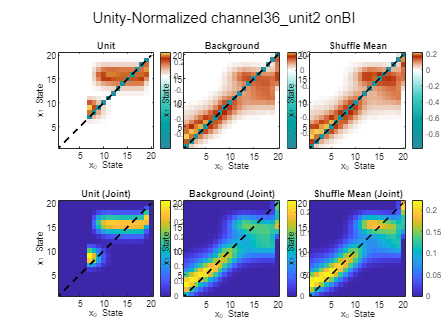

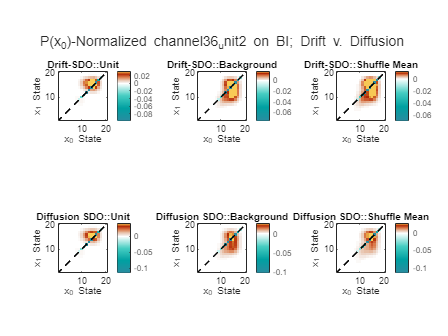

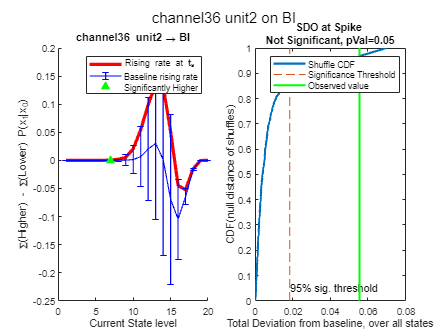

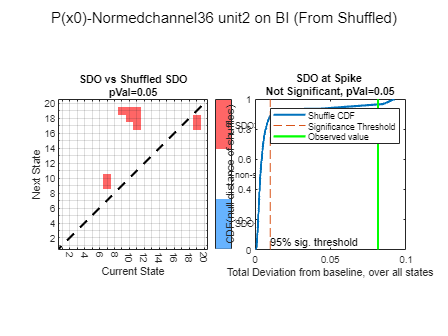

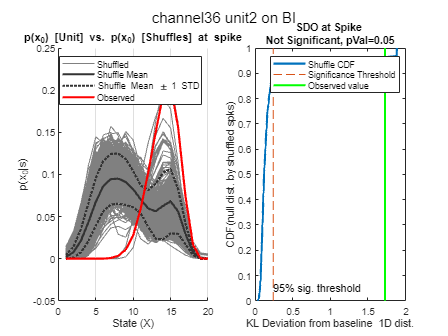

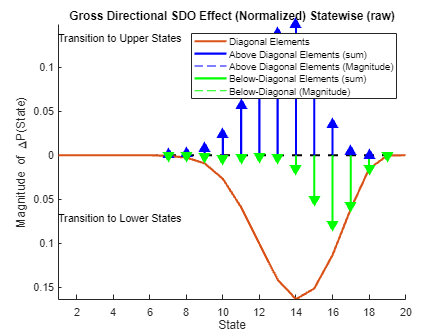

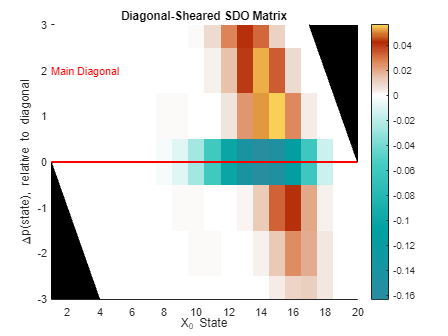

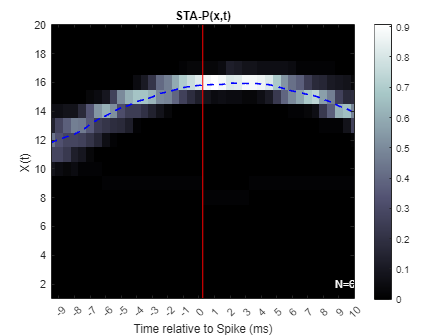

smm.plot(XT_CH_NO, PP_CH_NO); 

NOTE: Here, the 'background' SDO is calculated using ALL time points in the *xtDataCell* channel, and is more accurate than the approximation used in Method 1 (which estimates the background SDO from the covariance of signal state). Thus, there may be slight differences in the background SDO projected in Method 1 and Method 2. (The true background can be restored in Method 1 using the *.computeBackground* method for *pxtDataCell*, but this takes additional time and is rarely significant). 

#### Step 5: Evaluate Predictions

Use the *.predictError* method of the *sdoMultiMat* class, paired with the the *xtDataCell* and *ppDataCell* classes, and associated interesting indices to evaluate predictions of the spike-triggered SDO vs. the other hypothesized fit models. (*Note: All of these matrices are technically SDOs; The SDO Analysis Toolkit provides a common language to describe these models*) 

**Hypothesized Models**: 

- H1: (t0t1)     - No Change: The hypothesis that there is overall no change in the pre/post spike distribution (i.e., the spike has no associated correlation)

- H2: (Gauss) - Gaussian Diffusion: The hypothesis that there is no change in the mean of the post-spike distribution, but there may be an associated increase in variance (i.e. spike is associated with a change in signal, but it may not be predictable). 

- H3: (STA)     - Spike-Triggered Average: The hypothesis that the overall spike-triggered average effect, $\Delta P\left(x\right)$, is the same for all input states *x. *$p\left(x_1 \right)=p\left(x_0 \right)+\Delta P\left(x\right)$ for all x. 

- H4: (bck)     - Background SDO: The hypothesis that the change of signal observed around time of spike is no different than change of signal at unassociated regions. (This is a slighly more refined version of H1,     but accounts for baseline dynamics)

- H5: (mkv)     - Markov Matrix: The hypothesis that the distribution of signal in the post-spike state is predictable from modeling data predicted in the pre-spike state distribution as a first-order Markov process.

- H6: (staBck) - Spike-Triggered Averaged Effects on a Stochastic Background: This hypothesis assumes that the spike-triggered effect is invariant by state, but may be complicated by background system dynamics. 

- H7 (SDO):     - Spike-triggered SDO: This hypothesis permits the spike-triggered correlation to be state-dependent, and not adequately captured by background dynamics. 

Pre-spike and post-spike (ground-truth) distributions are generated as originally used in the SDO estimation. The prespike distribution is then fed to prediction matrices to predict the post-spike distribution. 

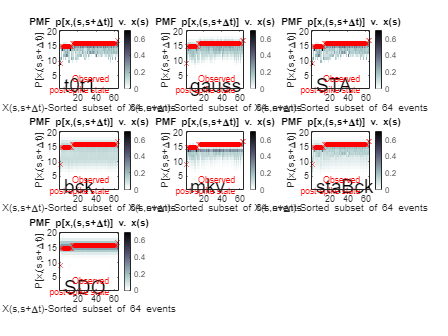

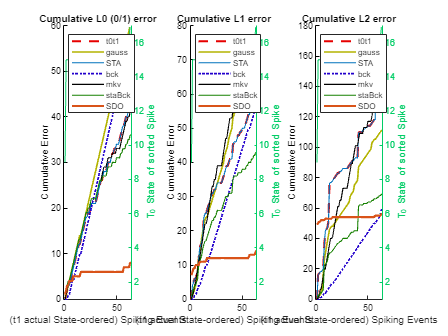

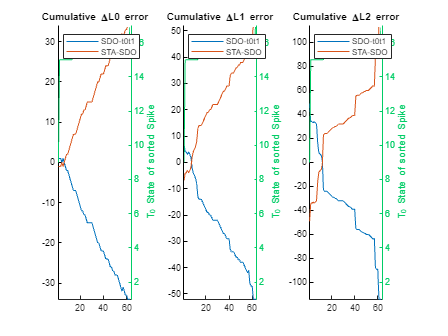

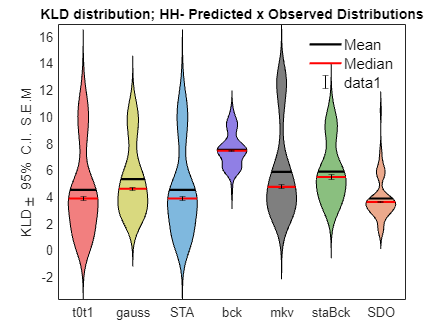

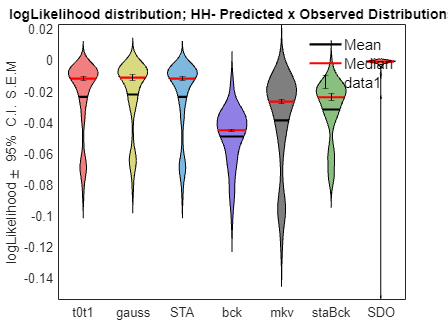

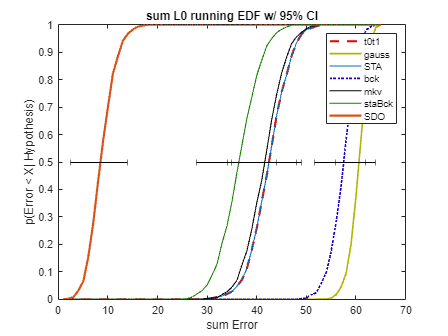

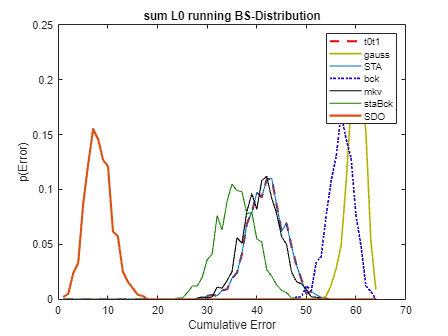

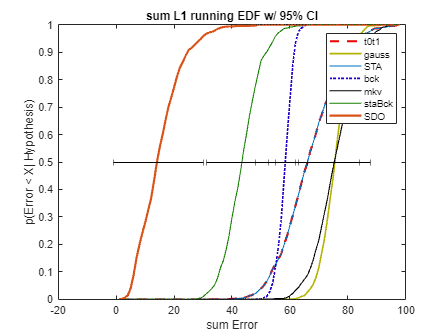

pE = smm.getPredictionError(xtdc,ppdc,XT_CH_NO,PP_CH_NO); %Genearate an instance of the 'predictionError' Class

pE.plot(); 

Multiple windows will pop up: 

- Stacked-bar chart of state-dependent error rates, by hypothesis. (Lower is better)

- State-ordered errror rates, by hypothesis. (Lower is better)

- Kullback–Leibler Divergence (KLD) between predicted and observed *distributions* of post-spike state. (Lower is better). 

- Log-Likelihood between predicted and observed *distributions* of post-spike state (Higher is better). 

- Empirical Distribution Function (EDF) of bootstrapped occurrence of error (E0), by hypothesis. 

- Distribution of bootstrapped occurrence of error (E0), by hypothesis.

- Empirical Distribution Function (EDF) of bootstrapped magnitude of error (E1), by hypothesis. 

- Distribution of bootstrapped magnitude of error (E1), by hypothesis.

- Empirical Distribution Function (EDF) of median Kullback–Leibler Divergence (KLD) across bootstrapped distributions. (Lower is better)

- Distribution of median Kullback–Leibler Divergence (KLD) across bootstrapped distributions. (Lower is better)

- Empirical Distribution Function (EDF) of median Log-Likelihood across bootstrapped distributions. (Higher is better)

- Distribution of median Log-Likelihood across bootstrapped distributions. (Higher is better)

% cleanup unnecessary variables from workspace
clear xtFile fdir1 ppFile xtData0 ppData0